order(K_mu_max_order)

ans = 15

K_mu_r_order=minreal(K_mu_max_order,0.8);
order(K_mu_r_order)

ans = 5

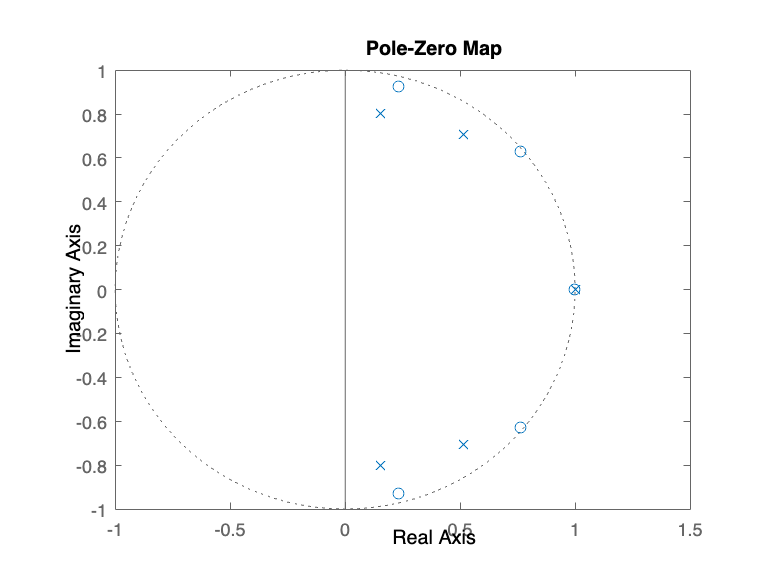

pzmap(K_mu_r_order)


S_mu_r_order = feedback( 1 , G * K_mu_r_order ) ;
T_mu_r_order = feedback( G * K_mu_r_order , 1 ) ;
U_mu_r_order = feedback( K_mu_r_order , G ) ;

if isstable(T_mu_r_order)==1
    disp("The system is stable")
else
    disp("The system is unstable")
end

The system is stable


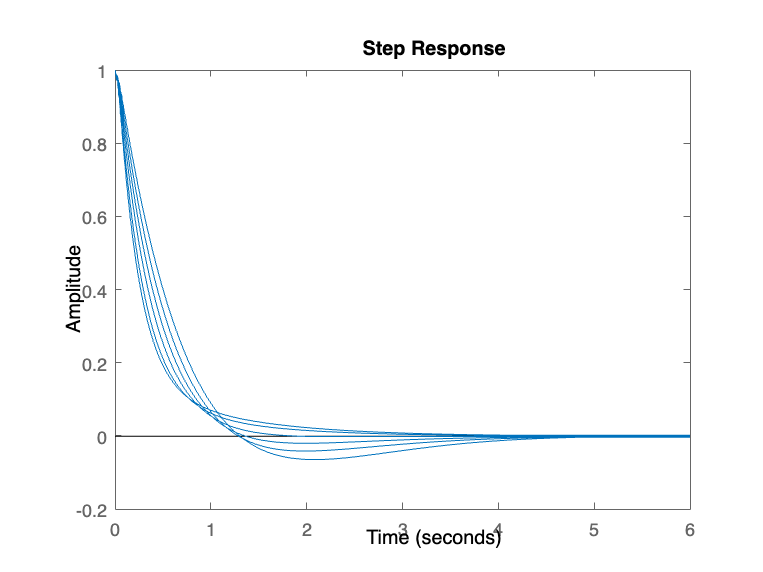


figure(13)
step(S_mu_r_order);

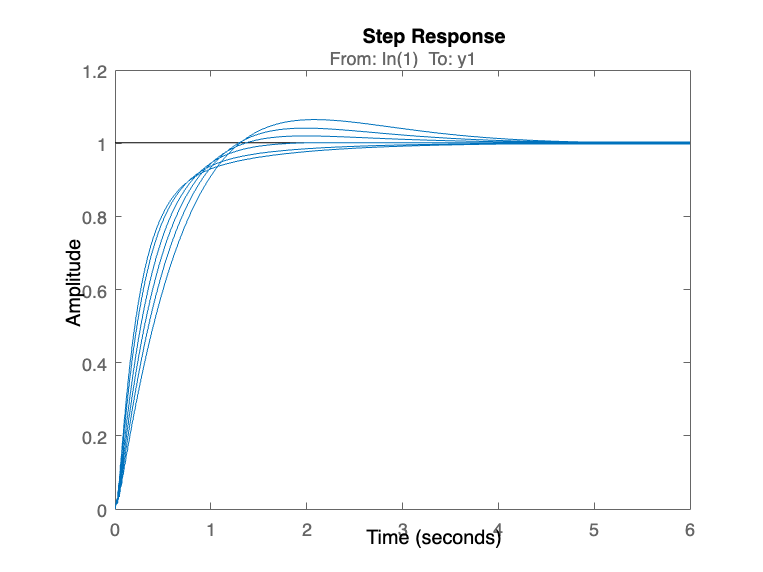

step(T_mu_r_order);

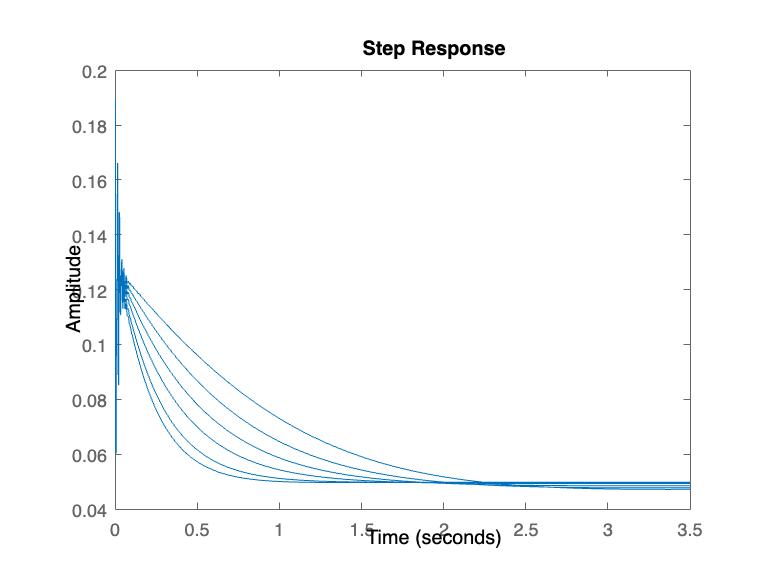

step(U_mu_r_order);

S_full = stepinfo( T_mu_max_order(:,:,4,1) ) ;
S_reduce = stepinfo( T_mu_r_order(:,:,4,1) ) ;

Field = {'RiseTime' ; 'TransientTime' ; 'SettlingMin' ; 'SettlingMax' ; 'Overshoot' ; 'Undershoot' ; 'Peak'; 'PeakTime' } ; 
Full_order = [ S_full.(cell2mat(Field(1)) ) ; S_full.(cell2mat(Field(2)) ) ; S_full.(cell2mat(Field(3)) ) ; S_full.(cell2mat(Field(4)) ) ; S_full.(cell2mat(Field(5)) ) ; S_full.(cell2mat(Field(6)) ) ; S_full.(cell2mat(Field(7)) ) ; S_full.(cell2mat(Field(8)) ) ] ; 
Reduce_order = [ S_reduce.(cell2mat(Field(1)) ) ; S_reduce.( cell2mat( Field(2) ) ) ; S_reduce.(cell2mat( Field(3) ) ) ; S_reduce.(cell2mat(Field(4)) ) ; S_reduce.(cell2mat(Field(5)) ) ; S_reduce.(cell2mat(Field(6)) ) ; S_reduce.(cell2mat(Field(7) ) ) ; S_reduce.(cell2mat( Field(8) ) ) ] ; 
relative_error = abs(Reduce_order - Full_order) ./ abs(Full_order);
T = table( Field , Full_order , Reduce_order , relative_error ) ;
disp( T ) ; 

          Field          Full_order    Reduce_order    relative_error
    _________________    __________    ____________    ______________

    {'RiseTime'     }        0.756          0.748          0.010582  
    {'TransientTime'}        1.308            1.3         0.0061162  
    {'SettlingMin'  }      0.90154        0.90147        8.7639e-05  
    {'SettlingMax'  }       1.0015         1.0017        0.00016917  
    {'Overshoot'    }     0.026977       0.043007            0.5942  
    {'Undershoot'   }            0              0               NaN  
    {'Peak'         }       1.0015         1.0017        0.00016917  
    {'PeakTime'     }        2.038          2.038                 0  

